%% AUTOENCODER SU VOLTI (MLX)
% Questo script addestra un semplice autoencoder (fully connected)
% sui dati dei volti e visualizza le ricostruzioni.
% Tutto fatto "a mano", senza toolbox esterni.
%% autoencoder_svd.m
% Pipeline SVD_BC → Autoencoder sui coefficienti principali

clear; clc; close all;
rng(0);

%% ----------------------------------------------------------------
%% 0) IMPOSTAZIONE AMBIENTE & CARTELLA RISULTATI
%% ----------------------------------------------------------------
projectRoot = '/Users/giuseppebonomo/Desktop/UNIPA CdLM Ing_Informatica/1 anno 2023-2024/1 Semestre 2023-2024/Metodi Numerici Avanzati/ProgettoMetodi';
addpath(genpath(projectRoot));   

this_folder  = pwd;
results_path = fullfile(this_folder,'results');
if ~exist(results_path,'dir')
    mkdir(results_path);
    fprintf('>>> Creo la cartella results\n');
end

%% ----------------------------------------------------------------
%% 1) PARAMETRI SVD
%% ----------------------------------------------------------------
tol   = 1e-4;
maxit = 1000;
energy_threshold = 0.95;   % mantieni il 95% dell’energia

%% ----------------------------------------------------------------
%% 2) CARICAMENTO DATASET ORL & MEAN FACE
%% ----------------------------------------------------------------
fprintf('>>> Caricamento dataset ORL...\n');  t = tic;

>>> Caricamento dataset ORL...


load('dataset/volti_dataset_Yale.mat');  % A (m×n), labels (ignored)
A = double(A)/255;
fprintf('   fatto in %.2f s\n', toc(t));

   fatto in 0.05 s



[m, n] = size(A);
img_h = 112;  img_w = 92;

fprintf('>>> Calcolo volto medio...\n');  t = tic;

>>> Calcolo volto medio...


mean_face = mean(A,2);
save(fullfile(results_path,'mean_face.mat'),'mean_face');
fprintf('   ok in %.2f s\n', toc(t));

   ok in 0.04 s



fprintf('>>> Centratura dati...\n');  t = tic;

>>> Centratura dati...


A_centered = A - mean_face;
fprintf('   ok in %.2f s\n', toc(t));

   ok in 0.01 s



%% ----------------------------------------------------------------
%% 3) SVD_BC su dati centrati
%% ----------------------------------------------------------------
fprintf('>>> Lancio svd_BC (tol=%.1e, maxit=%d)...\n', tol, maxit);

>>> Lancio svd_BC (tol=1.0e-04, maxit=1000)...


t = tic;
[U, S, V] = svd_BC(A_centered, tol, maxit);

   [svd_BC] costruisco ATA...
   [svd_BC] chiamo qr_eig su 165x165 (tol=1.0e-04,maxit=1000)...
         [qr_eig] deflazione k=165 ... 

iter=1001 time=2.24 s
         [qr_eig] deflazione k=164 ... 

iter=1001 time=1.93 s
         [qr_eig] deflazione k=163 ... 

iter=1001 time=2.15 s
         [qr_eig] deflazione k=162 ... iter=338 time=0.90 s
         [qr_eig] deflazione k=161 ... 

iter=1001 time=2.11 s
         [qr_eig] deflazione k=160 ... iter=309 time=0.55 s
         [qr_eig] deflazione k=159 ... 

iter=1001 time=1.89 s
         [qr_eig] deflazione k=158 ... 

iter=1001 time=1.50 s
         [qr_eig] deflazione k=157 ... 

iter=1001 time=1.78 s
         [qr_eig] deflazione k=156 ... iter=765 time=1.20 s
         [qr_eig] deflazione k=155 ... 

iter=1001 time=1.46 s
         [qr_eig] deflazione k=154 ... 

iter=1001 time=1.52 s
         [qr_eig] deflazione k=153 ... 

iter=1001 time=1.42 s
         [qr_eig] deflazione k=152 ... 

iter=1001 time=1.42 s
         [qr_eig] deflazione k=151 ... 

iter=1001 time=1.40 s
         [qr_eig] deflazione k=150 ... 

iter=1001 time=1.40 s
         [qr_eig] deflazione k=149 ... 

iter=1001 time=1.50 s
         [qr_eig] deflazione k=148 ... 

iter=1001 time=1.32 s
         [qr_eig] deflazione k=147 ... 

iter=1001 time=1.33 s
         [qr_eig] deflazione k=146 ... 

iter=1001 time=1.36 s
         [qr_eig] deflazione k=145 ... 

iter=1001 time=1.32 s
         [qr_eig] deflazione k=144 ... 

iter=1001 time=1.62 s
         [qr_eig] deflazione k=143 ... 

iter=1001 time=1.22 s
         [qr_eig] deflazione k=142 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=141 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=140 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=139 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=138 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=137 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=136 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=135 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=134 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=133 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=132 ... 

iter=1001 time=0.87 s
         [qr_eig] deflazione k=131 ... 

iter=1001 time=0.85 s
         [qr_eig] deflazione k=130 ... 

iter=1001 time=0.83 s
         [qr_eig] deflazione k=129 ... 

iter=1001 time=0.82 s
         [qr_eig] deflazione k=128 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=127 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=126 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=125 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=124 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=123 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=122 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=121 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=120 ... iter=90 time=0.06 s
         [qr_eig] deflazione k=119 ... 

iter=1001 time=0.72 s
         [qr_eig] deflazione k=118 ... 

iter=1001 time=0.70 s
         [qr_eig] deflazione k=117 ... 

iter=1001 time=0.68 s
         [qr_eig] deflazione k=116 ... 

iter=1001 time=0.67 s
         [qr_eig] deflazione k=115 ... 

iter=1001 time=0.67 s
         [qr_eig] deflazione k=114 ... iter=2 time=0.00 s
         [qr_eig] deflazione k=113 ... iter=514 time=0.33 s
         [qr_eig] deflazione k=112 ... 

iter=1001 time=0.62 s
         [qr_eig] deflazione k=111 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=110 ... 

iter=1001 time=0.61 s
         [qr_eig] deflazione k=109 ... 

iter=1001 time=0.60 s
         [qr_eig] deflazione k=108 ... 

iter=1001 time=0.59 s
         [qr_eig] deflazione k=107 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=106 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=105 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=104 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=103 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=102 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=101 ... iter=989 time=0.52 s
         [qr_eig] deflazione k=100 ... 

iter=1001 time=0.51 s
         [qr_eig] deflazione k=99 ... 

iter=1001 time=0.51 s
         [qr_eig] deflazione k=98 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=97 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=96 ... 

iter=1001 time=0.47 s
         [qr_eig] deflazione k=95 ... 

iter=1001 time=0.48 s
         [qr_eig] deflazione k=94 ... 

iter=1001 time=0.46 s
         [qr_eig] deflazione k=93 ... 

iter=1001 time=0.45 s
         [qr_eig] deflazione k=92 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=91 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=90 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=89 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=88 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=87 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=86 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=85 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=84 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=83 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=82 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=81 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=80 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=79 ... 

iter=1001 time=0.35 s
         [qr_eig] deflazione k=78 ... 

iter=1001 time=0.34 s
         [qr_eig] deflazione k=77 ... iter=344 time=0.11 s
         [qr_eig] deflazione k=76 ... 

iter=1001 time=0.32 s
         [qr_eig] deflazione k=75 ... 

iter=1001 time=0.32 s
         [qr_eig] deflazione k=74 ... 

iter=1001 time=0.31 s
         [qr_eig] deflazione k=73 ... 

iter=1001 time=0.30 s
         [qr_eig] deflazione k=72 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=71 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=70 ... iter=906 time=0.25 s
         [qr_eig] deflazione k=69 ... 

iter=1001 time=0.28 s
         [qr_eig] deflazione k=68 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=67 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=66 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=65 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=64 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=63 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=62 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=61 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=60 ... 

iter=1001 time=0.22 s
         [qr_eig] deflazione k=59 ... 

iter=1001 time=0.22 s
         [qr_eig] deflazione k=58 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=57 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=56 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=55 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=54 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=53 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=52 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=51 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=50 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=49 ... iter=2 time=0.00 s
         [qr_eig] deflazione k=48 ... 

iter=1001 time=0.16 s
         [qr_eig] deflazione k=47 ... 

iter=1001 time=0.15 s
         [qr_eig] deflazione k=46 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=45 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=44 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=43 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=42 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=41 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=40 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=39 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=38 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=37 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=36 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=35 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=34 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=33 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=32 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=31 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=30 ... iter=0 time=0.00 s
         

fprintf('   completata in %.2f s\n', toc(t));

   completata in 51.32 s


save(fullfile(results_path,'svd_data.mat'),'U','S','V');

%% ----------------------------------------------------------------
%% 4) Selezione k tramite energia cumulata
%% ----------------------------------------------------------------
eigvals = diag(S);
energy = cumsum(eigvals)/sum(eigvals);
k = find(energy>energy_threshold,1);
fprintf('>>> Trovati k = %d componenti (%.1f%% energia)\n', k, 100*energy(k));

>>> Trovati k = 161 componenti (95.4% energia)



%% ----------------------------------------------------------------
%% 5) Calcolo delle proiezioni PCA [k×n]
%% ----------------------------------------------------------------
% 1) Calcolo e normalizzo le proiezioni
P       = U(:,1:k)' * (A - mean_face);      % [k×n]
mu_P    = mean(P,2);                        
sigma_P = std(P,0,2) + eps;                 
P_norm  = (P - mu_P) ./ sigma_P;            % normalizzazione

% 2) Preparo X per l’autoencoder
X = P_norm';  % [n×k]

%% ----------------------------------------------------------------
%% 7) Parametri Autoencoder
%% ----------------------------------------------------------------
epochs        = 50;
learning_rate = 0.01;
bottleneck    = 40;   % dimensione del codice nel mezzo

%% ----------------------------------------------------------------
%% 8) Training Autoencoder
%% ----------------------------------------------------------------
fprintf('>>> Training autoencoder su coefficienti PCA (bottleneck = %d)...\n', bottleneck);

>>> Training autoencoder su coefficienti PCA (bottleneck = 40)...


t = tic;
[W_enc, b_enc, W_dec, b_dec, loss_history] = ...
    autoencoder_train(X, bottleneck, epochs, learning_rate);

[AE] Epoch 10/50, MSE=0.69666
[AE] Epoch 20/50, MSE=0.43118
[AE] Epoch 30/50, MSE=0.32772
[AE] Epoch 40/50, MSE=0.26389
[AE] Epoch 50/50, MSE=0.21980


fprintf('   Fine training in %.2f s\n', toc(t));

   Fine training in 0.24 s


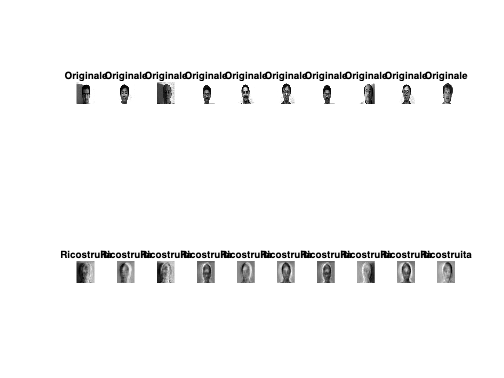


save(fullfile(results_path,'ae_weights.mat'), 'W_enc','b_enc','W_dec','b_dec','loss_history');

%% ----------------------------------------------------------------
%% 9) Visualizzazione delle ricostruzioni
%% ----------------------------------------------------------------

% Ricreo U_k se necessario
if ~exist('U_k','var')
    load(fullfile(results_path,'svd_data.mat'),'U');
    k   = size(W_enc,2);   % bottleneck della fase PCA→AE
    U_k = U(:,1:k);
end

num_show = 10;
perm = randperm(n, num_show);

figure('Name','Autoencoder + PCA: ricostruzioni','NumberTitle','off');
for i = 1:num_show
    % 1) prendo la riga i-esima di X → colonna
    x_pca = X(perm(i), :)';            

    % 2) forward through AE
    h     = max(0, W_enc * x_pca + b_enc);
    x_hat = W_dec * h + b_dec;        % [k × 1] = ricostruzione in spazio PCA

    % 3) torno allo spazio pixel: U_k*x_hat + mean_face
    x_rec = U_k * x_hat + mean_face;  % [m × 1]

    % 4) Originale e ricostruita
    subplot(2, num_show, i);
    imshow(reshape(A(:,perm(i)), img_h, img_w), []);
    title('Originale');

    subplot(2, num_show, i+num_show);
    imshow(reshape(x_rec, img_h, img_w), []);
    title('Ricostruita');
end
saveas(gcf, fullfile(results_path,'ae_pca_reconstructions.png'));

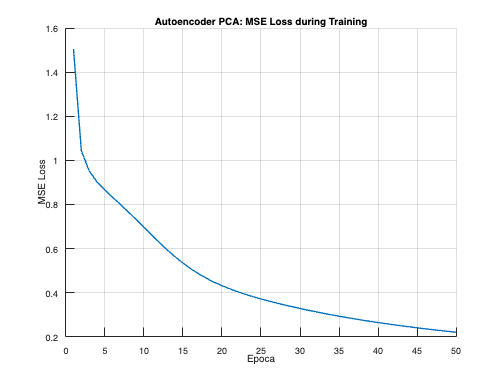


%% ----------------------------------------------------------------
%% 10) Andamento della loss
%% ----------------------------------------------------------------
figure; hold on;
plot(1:epochs, loss_history, 'LineWidth',1.5);
xlabel('Epoca'); ylabel('MSE Loss');
title('Autoencoder PCA: MSE Loss during Training');
grid on;
saveas(gcf, fullfile(results_path,'ae_pca_loss.png'));


fprintf('>>> Fine script (totale %.2f s)\n', toc);

>>> Fine script (totale 59.91 s)
